## Single MEKF Update

The following code tests an with ideal sensors two MEKF

No propagation/reset

q_rot = eul2quat([-1 0.1 0.8]);
q_n2m = eul2quat([0 0 0]);

x = zeros(6,1);

r1 = [0.9965 0 0];
b1 = quatrotate(q_rot,r1);

r2 = [-2.3e-05 -1.2e-06 -1.9e-06];
b2 = quatrotate(q_rot,r2);


P = diag([1*ones(1,3), 1*ones(1,3)]);

omega = [0 ;0;0];
beta = [0;0;0];

dt = 0.1;

G = [-eye(3), zeros(3);
    zeros(3), eye(3)];

sigma_v = 0.25;
sigma_u = 0.25;

Q = [sigma_v^2*eye(3), zeros(3);
    zeros(3), sigma_u^2*eye(3)];

delta_x = zeros(6,1);

for i=1:100000
    [q_n2m,P,delta_x] = singleMEKF(b1,r1,P,0.5,q_n2m,delta_x);
    [q_n2m,P,delta_x] = singleMEKF(b2,r2,P,0.5,q_n2m,delta_x);
end

## Full MEKF with Two Reference Vectors

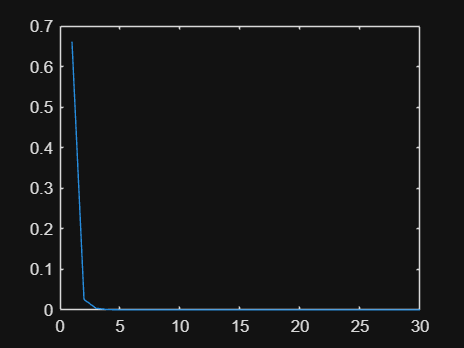

P = diag([1*ones(1,3), 1*ones(1,3)]);

q_diff = eul2quat(rand(1,3)*pi/180*10);
q_rot = eul2quat(rand(1,3)*2*pi);
q_n2m = compact(quaternion(q_diff)*quaternion(q_rot));
q_n2m = q_n2m/norm(q_n2m);

ref_ss = rand(1,3)*2-1;
ref_ss = ref_ss/norm(ref_ss);
mes_ss_i = quatrotate(q_rot,ref_ss);
use_sun_sensor = 1;

ref_mag = rand(1,3)*2-1;
ref_mag = ref_mag/norm(ref_mag);
mes_mag_i = quatrotate(q_rot,ref_mag);
use_magnometer = 1;

mes_var_ss = 0.01;
mes_var_mg = 0.1;

dt = 0.05;

N = 30;
angle_diff = zeros(1,N);

q_rel = quatmultiply(q_rot, quatinv(q_n2m));
cos_theta_over_2 = abs(q_rel(1));
angle_diff_i = 2 * acosd(cos_theta_over_2);

for i = 1:N

    mes_ss = mes_ss_i;% + rand(1,3)*0;
    mes_ss = mes_ss/norm(mes_ss);
    mes_mag = mes_mag_i;% + rand(1,3)*0;
    mes_mag = mes_mag/norm(mes_mag);

    %initialize
    delta_x = zeros(6,1);

    %loop over measurment vectors

    %magnometer
        if use_magnometer
            [q_n2m,P,delta_x] = singleMEKF(mes_mag,ref_mag,P,mes_var_mg,q_n2m,delta_x);
            P = P_clip(P,1000);
        end    
    
    %sun sensor
        if use_sun_sensor
            c1 = singleMEKF(mes_ss,ref_ss,P,mes_var_ss,q_n2m,delta_x);
            c2 = sunSensor_singleMEKF(mes_ss,ref_ss,P,mes_var_ss,90,q_n2m,delta_x);
            if c1 ~= c2
                disp("UNEQUAL")
            end
            [q_n2m,P,delta_x] = singleMEKF(mes_ss,ref_ss,P,mes_var_ss,q_n2m,delta_x);
            P = P_clip(P,1000);
        end

    %reset
    x_extra = [0 ; delta_x(1:3)]';

    q_n2m = q_n2m + (0.5*quatmultiply(q_n2m,x_extra));
    q_n2m = q_n2m/norm(q_n2m);

    w = zeros(3);

    G = [-eye(3), zeros(3);
         zeros(3), eye(3)];

    Q = [1^2*eye(3), zeros(3);
         zeros(3), 1^2*eye(3)];

    F = [w, eye(3);
         zeros(3), zeros(3)];

    dot_P = F*P + P*F'+G*Q*G';
    P = P + dot_P*dt;
    P = P_clip(P,1000);

    q_rel = quatmultiply(q_rot, quatinv(q_n2m));
    cos_theta_over_2 = clip(abs(q_rel(1)),-1,1);
    angle_diff(i) = 2 * acosd(cos_theta_over_2);
end

plot(angle_diff)

angle_diff(N)

ans = 0

angle_diff_i

angle_diff_i = 12.2526


q_rot

q_rot =     0.3823   -0.3419   -0.8565    0.0574


q_n2m

q_n2m =     0.3823   -0.3419   -0.8565    0.0574



disp("")
disp("")

## Single MEKF with One Sun Sensor

P = diag([1*ones(1,3), 1*ones(1,3)]);

q_diff = eul2quat(rand(1,3)*pi/180*30);
q_rot = eul2quat(rand(1,3)*2*pi);
q_n2m = compact(quaternion(q_diff)*quaternion(q_rot));
q_n2m = q_n2m/norm(q_n2m);

min_angle_ss = 55;

ref_sun = rand(1,3) + [1 0 0];
ref_sun = ref_sun/norm(ref_sun);
ref_ssensor = [1 0 0]; %rand(1,3)*2-1;
ref_ssensor = ref_ssensor/norm(ref_ssensor);
dot(quatrotate(q_n2m,ref_sun),ref_ssensor)

ans = -0.5901

mes_ss_i = dot(quatrotate(q_rot,ref_sun),ref_ssensor)

mes_ss_i = -0.4604

mes_ss_i = (mes_ss_i > cosd(min_angle_ss))*mes_ss_i;
mes_ss_i = ref_ssensor*mes_ss_i

mes_ss_i =      0     0     0


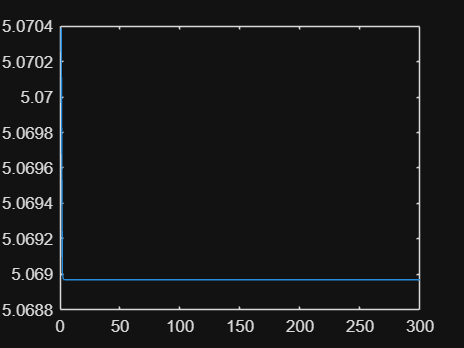


ref_mag = rand(1,3)*2-1;
ref_mag = ref_mag/norm(ref_mag);
mes_mag_i = quatrotate(q_rot,ref_mag);

mes_var_ss = 0.01;
mes_var_mg = 0.1;

dt = 0.05;

N = 300;
angle_diff = zeros(1,N);

q_rel = quatmultiply(q_rot, quatinv(q_n2m));
cos_theta_over_2 = abs(q_rel(1));
angle_diff_i = 2 * acosd(cos_theta_over_2);

for i = 1:N

    mes_ss = mes_ss_i;% + rand(1,3)*0;
    mes_mag = mes_mag_i;% + rand(1,3)*0;
    mes_mag = mes_mag/norm(mes_mag);
    
    delta_x = zeros(6,1);

    [q_n2m,P,delta_x] = sunSensor_singleMEKF(mes_ss,ref_sun,P,mes_var_ss,min_angle_ss,q_n2m,delta_x);
    [q_n2m,P,delta_x] = singleMEKF(mes_mag,ref_mag,P,mes_var_mg,q_n2m,delta_x);

    x_extra = [0 ; delta_x(1:3)]';

    q_n2m = q_n2m + (0.5*quatmultiply(q_n2m,x_extra));
    q_n2m = q_n2m/norm(q_n2m);

    w = zeros(3);

    G = [-eye(3), zeros(3);
         zeros(3), eye(3)];

    Q = [1^2*eye(3), zeros(3);
         zeros(3), 1^2*eye(3)];

    F = [w, eye(3);
         zeros(3), zeros(3)];

    dot_P = F*P + P*F'+G*Q*G';
    P = P + dot_P*dt;
    P = P_clip(P,1000);

    q_rel = quatmultiply(q_rot, quatinv(q_n2m));
    cos_theta_over_2 = abs(q_rel(1));
    angle_diff(i) = 2 * acosd(cos_theta_over_2);
end

plot(angle_diff)

angle_diff(N)

ans = 5.0690

angle_diff_i

angle_diff_i = 9.5577


mes_ss = dot(quatrotate(q_n2m,ref_sun),ref_ssensor)

mes_ss = -0.4747

mes_ss = dot(quatrotate(q_rot,ref_sun),ref_ssensor)

mes_ss = -0.4604


mes_mag = quatrotate(q_n2m,ref_mag)

mes_mag =    -0.4435   -0.8067   -0.3906


mes_mag = quatrotate(q_rot,ref_mag)

mes_mag =    -0.4435   -0.8067   -0.3906



disp("")
disp("")

## Sun Sensor all sides

P = diag([1*ones(1,3), 1*ones(1,3)]);

q_diff = eul2quat(rand(1,3)*pi/180*10);
q_rot = eul2quat(rand(1,3)*2*pi);
q_n2m = compact(quaternion(q_diff)*quaternion(q_rot));
q_n2m = q_n2m/norm(q_n2m);

min_angle_ss = 55;

ref_ss = rand(1,3)*2-1;
ref_ss = ref_ss/norm(ref_ss);
mes_ss_i = quatrotate(q_rot,ref_ss);
mes_ss_i = (abs(mes_ss_i) > cosd(min_angle_ss)).*mes_ss_i

mes_ss_i =          0         0    0.9278


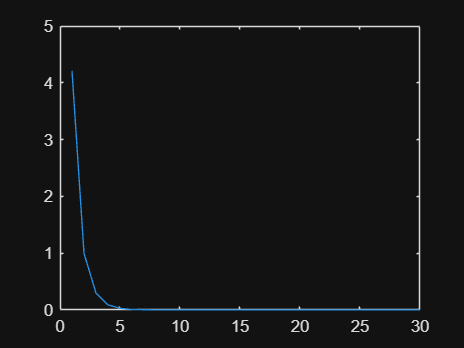


ref_mag = rand(1,3)*2-1;
ref_mag = ref_mag/norm(ref_mag);
mes_mag_i = quatrotate(q_rot,ref_mag);

mes_var_ss = 0.01;
mes_var_mg = 0.1;

dt = 0.05;

N = 30;
angle_diff = zeros(1,N);

q_rel = quatmultiply(q_rot, quatinv(q_n2m));
cos_theta_over_2 = abs(q_rel(1));
angle_diff_i = 2 * acosd(cos_theta_over_2);

for i = 1:N

    mes_ss = mes_ss_i;% + rand(1,3)*0;
    mes_mag = mes_mag_i;% + rand(1,3)*0;
    mes_mag = mes_mag/norm(mes_mag);

    %initialize
    delta_x = zeros(6,1);

    %loop over measurment vectors
    [q_n2m,P,delta_x] = singleMEKF(mes_mag,ref_mag,P,mes_var_mg,q_n2m,delta_x);
    P = P_clip(P,1000);

    [q_n2m,P,delta_x] = sunSensor_singleMEKF(mes_ss,ref_ss,P,mes_var_ss, ...
                                             q_n2m,delta_x);
    P = P_clip(P,1000);

    %reset
    x_extra = [0 ; delta_x(1:3)]';

    q_n2m = q_n2m + (0.5*quatmultiply(q_n2m,x_extra));
    q_n2m = q_n2m/norm(q_n2m);

    w = zeros(3);

    G = [-eye(3), zeros(3);
         zeros(3), eye(3)];

    Q = [1^2*eye(3), zeros(3);
         zeros(3), 1^2*eye(3)];

    F = [w, eye(3);
         zeros(3), zeros(3)];

    dot_P = F*P + P*F'+G*Q*G';
    P = P + dot_P*dt;
    P = P_clip(P,1000);

    q_rel = quatmultiply(q_rot, quatinv(q_n2m));
    cos_theta_over_2 = clip(abs(q_rel(1)),-1,1);
    angle_diff(i) = 2 * acosd(cos_theta_over_2);
end

plot(angle_diff)

angle_diff(N)

ans = 0

angle_diff_i

angle_diff_i = 12.0074


q_rot

q_rot =     0.5885    0.3200   -0.5128    0.5369


q_n2m

q_n2m =     0.5885    0.3200   -0.5128    0.5369



mes_ss = quatrotate(q_n2m,ref_ss);
mes_ss = (abs(mes_ss) > cosd(min_angle_ss)).*mes_ss

mes_ss =          0         0    0.9278


mes_ss = quatrotate(q_rot,ref_ss);
mes_ss = (abs(mes_ss) > cosd(min_angle_ss)).*mes_ss

mes_ss =          0         0    0.9278



mes_mag = quatrotate(q_n2m,ref_mag)

mes_mag =     0.5762    0.3244    0.7502


mes_mag = quatrotate(q_rot,ref_mag)

mes_mag =     0.5762    0.3244    0.7502



disp("")
disp("")

P = diag([1*ones(1,3), 1*ones(1,3)]);

q_diff = eul2quat(rand(1,3)*pi/180*10);
q_rot = eul2quat(rand(1,3)*2*pi);
q_n2m = compact(quaternion(q_diff)*quaternion(q_rot));
q_n2m = q_n2m/norm(q_n2m);

min_angle_ss = 55;

ref_ss = rand(1,3)*2-1;
ref_ss = ref_ss/norm(ref_ss);
mes_ss_i = quatrotate(q_rot,ref_ss);
mes_ss_i = (abs(mes_ss_i) > cosd(min_angle_ss)).*mes_ss_i;
mes_ss = mes_ss_i

mes_ss =     0.7212         0   -0.6391


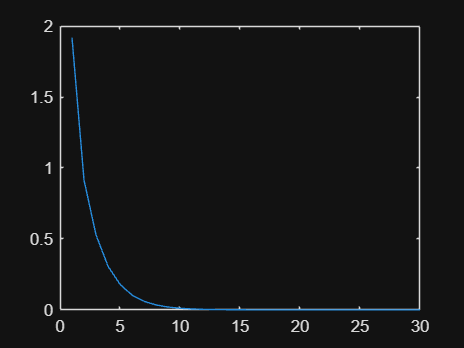


ref_mag = rand(1,3)*2-1;
ref_mag = ref_mag/norm(ref_mag);
mes_mag_i = quatrotate(q_rot,ref_mag);
mes_mag = mes_mag_i;


mes_var_ss = 0.1;
mes_var_mg = 0.1;

dt = 0.05;

N = 30;
angle_diff = zeros(1,N);

q_rel = quatmultiply(q_rot, quatinv(q_n2m));
cos_theta_over_2 = abs(q_rel(1));
angle_diff_i = 2 * acosd(cos_theta_over_2);

beta = zeros(1,3);
omega = zeros(1,3);
use_sun_sensor = 1;
use_magnometer = 1;
ref_aam = zeros(1,3);
mes_aam = zeros(1,3);
use_ang_acc_magentorquer = 0;
use_ang_vel = 0;
mes_var_aam = 0;
use_steve_mode = 0;
steve_ref = zeros(1,3);
steve_mes =zeros(1,3);


for i = 1:N

   [P, q_n2m,beta,hat_omega] = ...
   fullMEKF(P,q_n2m,beta,omega, ref_ss, mes_ss, use_sun_sensor, ...
            ref_mag, mes_mag, use_magnometer, ref_aam, mes_aam, ...
            use_ang_acc_magentorquer, use_ang_vel, mes_var_ss, ...
            mes_var_mg, mes_var_aam, min_angle_ss, dt, ...
            use_steve_mode, steve_ref, steve_mes);


    q_rel = quatmultiply(q_rot, quatinv(q_n2m));
    cos_theta_over_2 = clip(abs(q_rel(1)),-1,1);
    angle_diff(i) = 2 * acosd(cos_theta_over_2);
end

plot(angle_diff)

angle_diff(N)

ans = 0

angle_diff_i

angle_diff_i = 12.3725


q_rot

q_rot =    -0.0765    0.1112    0.3156   -0.9393


q_n2m

q_n2m =    -0.0765    0.1112    0.3156   -0.9393



mes_ss = quatrotate(q_n2m,ref_ss);
mes_ss = (abs(mes_ss) > cosd(min_angle_ss)).*mes_ss

mes_ss =     0.7212         0   -0.6391


mes_ss = quatrotate(q_rot,ref_ss);
mes_ss = (abs(mes_ss) > cosd(min_angle_ss)).*mes_ss

mes_ss =     0.7212         0   -0.6391



mes_mag = quatrotate(q_n2m,ref_mag)

mes_mag =    -0.2383    0.1761   -0.9551


mes_mag = quatrotate(q_rot,ref_mag)

mes_mag =    -0.2383    0.1761   -0.9551



disp("")
disp("")

P = diag([1*ones(1,3), 1*ones(1,3)]);

%q_diff = eul2quat(rand(1,3)*pi/180*10);
q_rot = eul2quat([0.59341,-1.0996,0.36652]);
%q_n2m = compact(quaternion(q_diff)*quaternion(q_rot));
q_n2m = [0.8677, 0.0716, -0.4740, 0.1311];
q_n2m = q_n2m/norm(q_n2m);

min_angle_ss = 55;

%ref_ss = [-1 1 0];
ref_ss = [0 0 1];
ref_ss = ref_ss/norm(ref_ss);
mes_ss_i = quatrotate(q_rot,ref_ss);
mes_ss_i = (abs(mes_ss_i) > cosd(min_angle_ss)).*mes_ss_i;
mes_ss = mes_ss_i

mes_ss =     0.8910         0         0


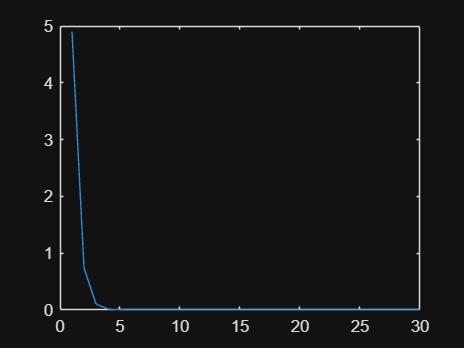


%ref_mag = [-2.3, -0.12, -0.19];
ref_mag = [-1 1 0];
ref_mag = ref_mag/norm(ref_mag);
mes_mag_i = quatrotate(q_rot,ref_mag);
mes_mag = mes_mag_i;

mes_var_ss = 0.01;
mes_var_mg = 0.1;

dt = 0.05;

N = 30;
angle_diff = zeros(1,N);

q_rel = quatmultiply(q_rot, quatinv(q_n2m));
cos_theta_over_2 = abs(q_rel(1));
angle_diff_i = 2 * acosd(cos_theta_over_2);

beta = zeros(1,3);
omega = zeros(1,3);
use_sun_sensor = 1;
use_magnometer = 1;
ref_aam = zeros(1,3);
mes_aam = zeros(1,3);
use_ang_acc_magentorquer = 0;
use_ang_vel = 0;
mes_var_aam = 0;
use_steve_mode = 0;
steve_ref = zeros(1,3);
steve_mes =zeros(1,3);


for i = 1:N

   [P, q_n2m,beta,hat_omega] = ...
   fullMEKF(P,q_n2m,beta,omega, ref_ss, mes_ss, use_sun_sensor, ...
            ref_mag, mes_mag, use_magnometer, ref_aam, mes_aam, ...
            use_ang_acc_magentorquer, use_ang_vel, mes_var_ss, ...
            mes_var_mg, mes_var_aam, min_angle_ss, dt, ...
            use_steve_mode, steve_ref, steve_mes);


    q_rel = quatmultiply(q_rot, quatinv(q_n2m));
    cos_theta_over_2 = clip(abs(q_rel(1)),-1,1);
    angle_diff(i) = 2 * acosd(cos_theta_over_2);
end

plot(angle_diff)

angle_diff(N)

ans = 1.7075e-06

angle_diff_i

angle_diff_i = 36.9854


q_rot

q_rot =     0.7739    0.2988   -0.4459    0.3362


q_n2m

q_n2m =     0.7739    0.2988   -0.4459    0.3362



mes_ss = quatrotate(q_n2m,ref_ss);
mes_ss = (abs(mes_ss) > cosd(min_angle_ss)).*mes_ss

mes_ss =     0.8910         0         0


mes_ss = quatrotate(q_rot,ref_ss);
mes_ss = (abs(mes_ss) > cosd(min_angle_ss)).*mes_ss

mes_ss =     0.8910         0         0



mes_mag = quatrotate(q_n2m,ref_mag)

mes_mag =    -0.0866    0.9774   -0.1931


mes_mag = quatrotate(q_rot,ref_mag)

mes_mag =    -0.0866    0.9774   -0.1931



disp("")
disp("")

## [Incomplete] Derivation of H for Sun Sensor

syms r1 r2 r3
H = sym(zeros(3))
dt = 0.001
q0 = [1,0,0,0]
r0 = [r1 r2 r3]
for idx = 1:3
    r = [0 0 0];
    r(idx) = 1;
    for idx2=1:3
        q = q0;
        q(idx2+1) = dt;
        b = quatrotate(q,r);
        H(idx2,:) = H(idx2,:)+round((r-b)/dt)*r0(idx);
    end
end
H

H = [   0  -r(3),  r(2);
      r(3),    0, -r(1);
     -r(2),  r(1),    0]

syms r1 r2 r3
H = sym(zeros(3))
dt = 0.001
q0 = [1,0,0,0]
r0 = [r1 r2 r3]

for idx = 1:1
    q = q0;
    q(idx+1) = dt;
    b = dot(quatrotate(q,r0),r0)
    round(b)
    %H(idx2,:) = H(idx2,:)+round((r-b)/dt)*r0(idx);
end
%H

H = [   0  -r(3),  r(2);
      r(3),    0, -r(1);
     -r(2),  r(1),    0]

ref_ss =[1 0 0];
ref_ss = ref_ss/norm(ref_ss);
mes_ss = quatrotate(q_n2m,ref_ss);
mes_ss = (mes_ss > cosd(55)).*mes_ss